#### Artificial data from previous assignment

clear;

Data set generation of exercise 2.4

% seed fixing as recommended in: https://nl.mathworks.com/help/matlab/math/updating-your-random-number-generator-syntax.html
rng('default');
% define mean and sd
mu1 = [0.4; 0.6];
sd1 = [0.9; 0.7];

mu2 = [2.5; 3.0];
sd2 = [0.9; 0.7];

% sizes
train_size = 1800;
c1_train_size = 1000;
c2_train_size = 800;

test_size = 900;
c1_test_size = 500;
c2_test_size = 400;

% Training set
% Class 1 - 1000
X_train_c1 = randn(2, c1_train_size) .* sd1 + mu1;
Y_train_c1 = ones(1, c1_train_size);

% Class 2 - 800
X_train_c2 = randn(2, c2_train_size) .* sd2 + mu2;
Y_train_c2 = -1*ones(1, c2_train_size);

X_train = [X_train_c1, X_train_c2];
Y_train = [Y_train_c1, Y_train_c2];

% Testing set
% Class 1 - 500
X_test_c1 = randn(2, c1_test_size) .* sd1 + mu1;
Y_test_c1 = ones(1, c1_test_size);

% Class 2 - 400
X_test_c2 = randn(2, c2_test_size) .* sd2 + mu2;
Y_test_c2 = -1*ones(1, c2_test_size);

X_test = [X_test_c1, X_test_c2];
Y_test = [Y_test_c1, Y_test_c2];

Cross validation. 

% Only use training data for CV
X_all = X_train;
Y_all = Y_train;

num_repetitions = 10;
num_folds = 10;
all_accuracies = zeros(num_repetitions, num_folds);

for rep = 1:num_repetitions
    indices = crossvalind('Kfold', Y_all, num_folds);
    
    for fold = 1:num_folds
        test_idx  = (indices == fold);
        train_idx = ~test_idx;
        
        X_cv_train = X_all(:, train_idx);
        Y_cv_train = Y_all(train_idx);
        X_cv_test = X_all(:, test_idx);
        Y_cv_test = Y_all(test_idx);
        
        [~, fold_acc_test, ~, ~, ~] = custom_LDA(X_cv_train, Y_cv_train, X_cv_test, Y_cv_test);
        all_accuracies(rep, fold) = fold_acc_test;
    end
end

Test Set Accuracy: 100.00%
Train Set Accuracy: 97.96%
Test Set Accuracy: 98.33%
Train Set Accuracy: 98.02%
Test Set Accuracy: 95.56%
Train Set Accuracy: 98.40%
Test Set Accuracy: 98.33%
Train Set Accuracy: 98.09%
Test Set Accuracy: 100.00%
Train Set Accuracy: 97.90%
Test Set Accuracy: 97.78%
Train Set Accuracy: 98.21%
Test Set Accuracy: 98.89%
Train Set Accuracy: 98.09%
Test Set Accuracy: 97.78%
Train Set Accuracy: 98.15%
Test Set Accuracy: 95.00%
Train Set Accuracy: 98.46%
Test Set Accuracy: 99.44%
Train Set Accuracy: 97.96%
Test Set Accuracy: 97.78%
Train Set Accuracy: 98.15%
Test Set Accuracy: 95.56%
Train Set Accuracy: 98.33%
Test Set Accuracy: 98.89%
Train Set Accuracy: 98.09%
Test Set Accuracy: 97.78%
Train Set Accuracy: 98.15%
Test Set Accuracy: 99.44%
Train Set Accuracy: 97.96%
Test Set Accuracy: 98.33%
Train Set Accuracy: 98.09%
Test Set Accuracy: 99.44%
Train Set Accuracy: 97.96%
Test Set Accuracy: 99.44%
Train Set Accuracy: 97.96%
Test Set Accuracy: 98.33%
Train Set Accuracy

% Evaluate the training model on the test set
mean_cv_accuracy = mean(all_accuracies(:));
std_cv_accuracy  = std(all_accuracies(:));
[~, accuracy, ~, ~, ~] = custom_LDA(X_train, Y_train, X_test, Y_test);

Test Set Accuracy: 97.44%
Train Set Accuracy: 98.11%



fprintf('Mean CV Accuracy: %.2f%%\n', mean_cv_accuracy * 100);

Mean CV Accuracy: 98.10%


fprintf('Std  CV Accuracy: %.2f%%\n', std_cv_accuracy  * 100);

Std  CV Accuracy: 1.06%


Scatter plot of the accuracies found from the cross validation across 10 repititions of 10 fold cross validation

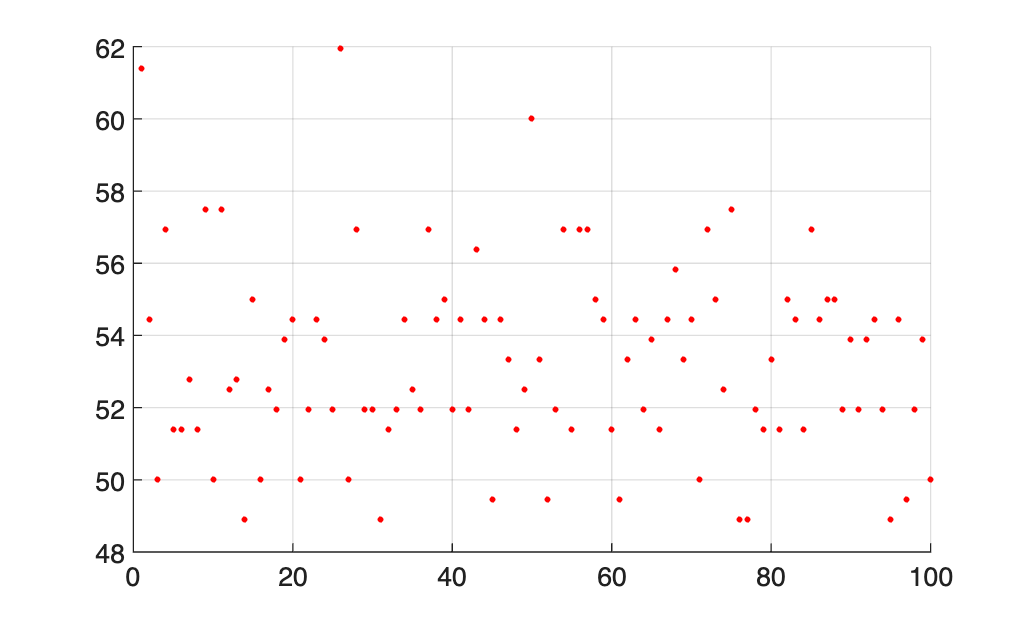

figure;
scatter(1:100, all_accuracies(:)'*100, 5, 'red', 'filled');
grid on

yline(mean_cv_accuracy*100, '--', 'LineWidth', 1.5, 'Color', 'black');

Unrecognized function or variable 'mean_cv_accuracy'.

title('CV Accuracy per Fold of artificial data');
xlabel('Fold (1-100)');
ylabel('Accuracy (%)');
ylim([90 101]);
legend('Fold accuracies', 'Mean CV');